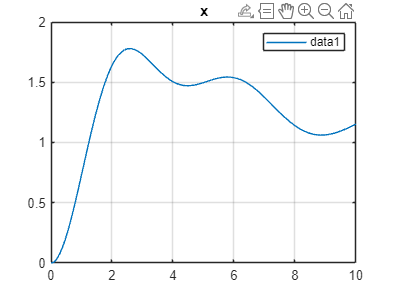

J = 1.0;
r = 0.4;
m = 0.5; 
k = 1.0;
b = 0.25; 
kt = 0.5;
bt = 0.25;
F = 1;

f=@(t,y)...
    [y(2);...
    (1/m) * (F-b*(y(2)-r*y(4))-k*(y(1)-r*y(3)));...
    y(4);...
    (1/J)*(r*(k*(y(1)-r*y(3)))+b*(y(2)-r*(y(4)))-bt*y(4)-kt*y(3))];

figure()
[t,y]= ode45(f, [0 10], [0, 0, 0, 0]);
plot(t,y(:,1)); title('x'); grid on;

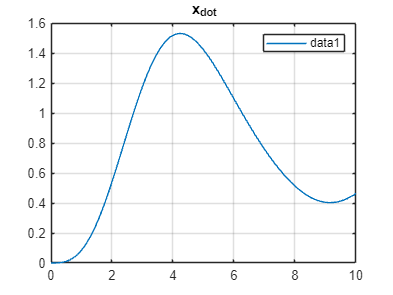

plot(t,y(:,3)); title('x_d_o_t'); grid on;

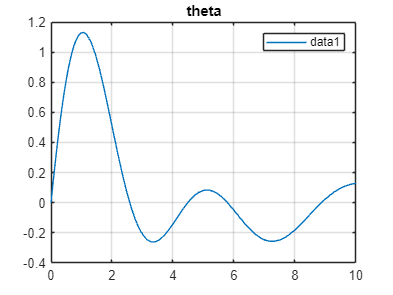

plot(t,y(:,2)); title('theta'); grid on;

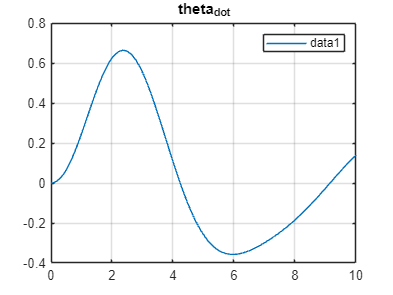

plot(t,y(:,4)); title('theta_d_o_t'); grid on;